# Raw signal dimensionality

We searched for two basis sets for the fluorescent data from the lip and tongue.  We are exploring the data with an excitation light of 415 nm.

This script restricts the analysis to 500-600 nm.  There is a parallel script that looks at the whole range (500-700).  The logic there will be different because there is porphyrin on the tongue, but not the lip.

**Analysis from 500-600nm**

- We can get an excellent match using 3 basis functions for **tongue **

- We asked whether using a linear model of the tongue, we can fit the lip data as well.  We find that from 500-600nm, **a 3 dimensional model of the tongue fits the lip data pretty well, 4 is very well.**

- We can fit the **lip well with 3 bases**, but not 2.

- We asked whether using a linear model of the lip, we can fit the tongue data.  We find that  **4 or more Lip bases fit the tongue data**.  This is a bit odd since the lip data themselves only need 3.

**Summary:  **If we use 4 dimensions, which overfit both the tongue and the lip a little bit, we can predict the other one as well.

**Note about tissue optics**

We explored whether we could make the two come together if we assume that there is a transmission function through the tissue that differs between tongue and lip.  That took us on an expedition of fitting using a diagonal matrix (wave x wave) to relate the two sets of basis functions.  We found a low dimensional parameterization of the diagonal matrix. The code is at the bottom of this script.

The tissue optics analysis did not help. So we put it aside for now.  The search methods, however, may prove to be helpful functions later.

## Initialize the database and ISET

ieInit;

% Wavelength samples
waves = 500:600;

% Read in the database
[T,dataDir] = oeDatabaseCreate;

% Normalize for unit length, using oeReadFiles.
normalizationP = 540;

% This checks the quality of the fit of the data.
dimensionality = [2 3 4 5];

% SVD criterion for explained variance, if less than 1.
% criterion = 0.999;
% 
% % If criterion is more than 1, then we treat it as the number of
% % dimensions.
% criterion = 3;
% 
% % The difference (delta) in dimensions between the tongue, which is always
% % equal (deltaDim = 0) or less than the number of dimensions for the lip.
% deltaDim = 0;

## Read the tongue data

We tried various normalization approaches.  They are all the same.  

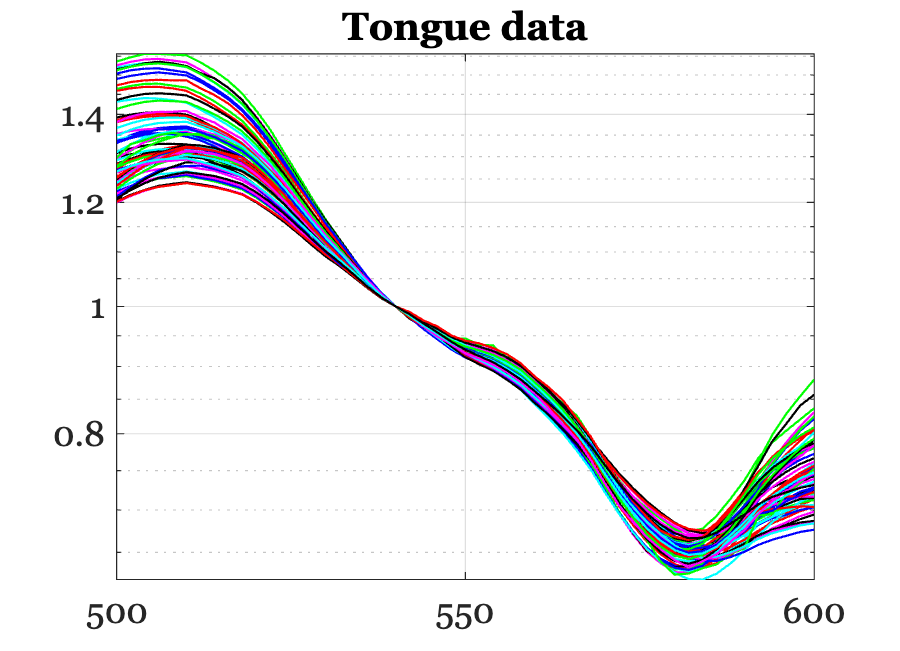

files405 = ieTableGet(T,...
    'ewave',405, ...
    'substrate','tongue');
files415 = ieTableGet(T,...
    'ewave',415, ...
    'substrate','tongue');
filesAll = cat(1,files405,files415);

dataTongue = oeReadFiles(filesAll,'waves',waves,'normalized wave',normalizationP);

ieFigure;
semilogy(waves,dataTongue);
grid on;
title('Tongue data');

## Set the dimensionality of the tongue data

Perform SVD explicitly, rather than using the pca() method.

[UT, ~, ~] = svd(dataTongue, 'econ');


## Plot the accuracy when using the linear model

These graphs show that 3 is good enough, with very small improvement when we go to 4 or 5.

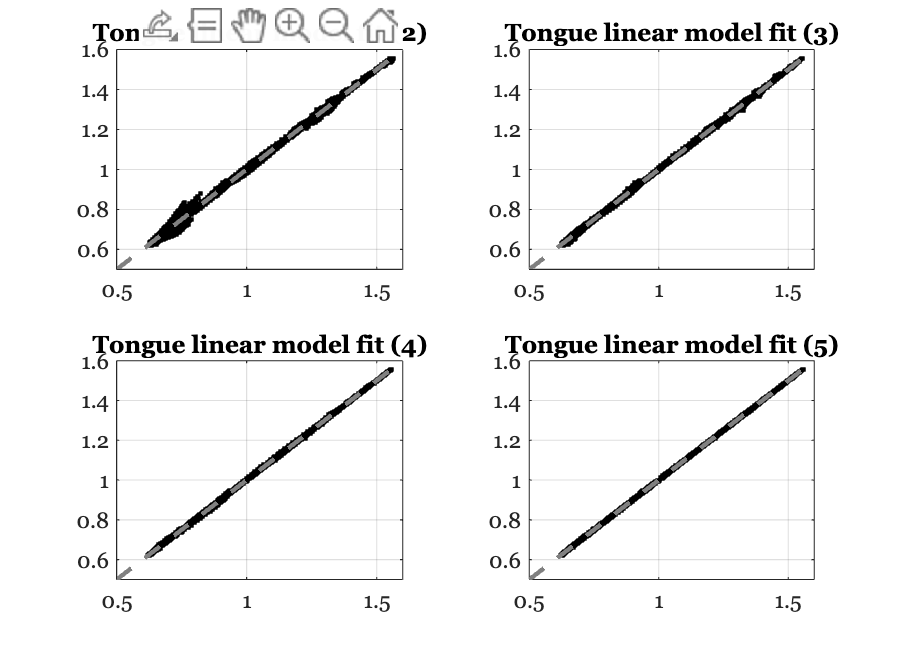

ieFigure;
tiledlayout(2,2);
for dd = dimensionality
    wgts = UT(:,1:dd)'*dataTongue;
    est = UT(:,1:dd)*wgts;
    nexttile;
    plot(est(:),dataTongue(:),'k.');
    identityLine;
    grid on;
    title(sprintf('Tongue linear model fit (%d)',dd));
end

## Read the Lip data

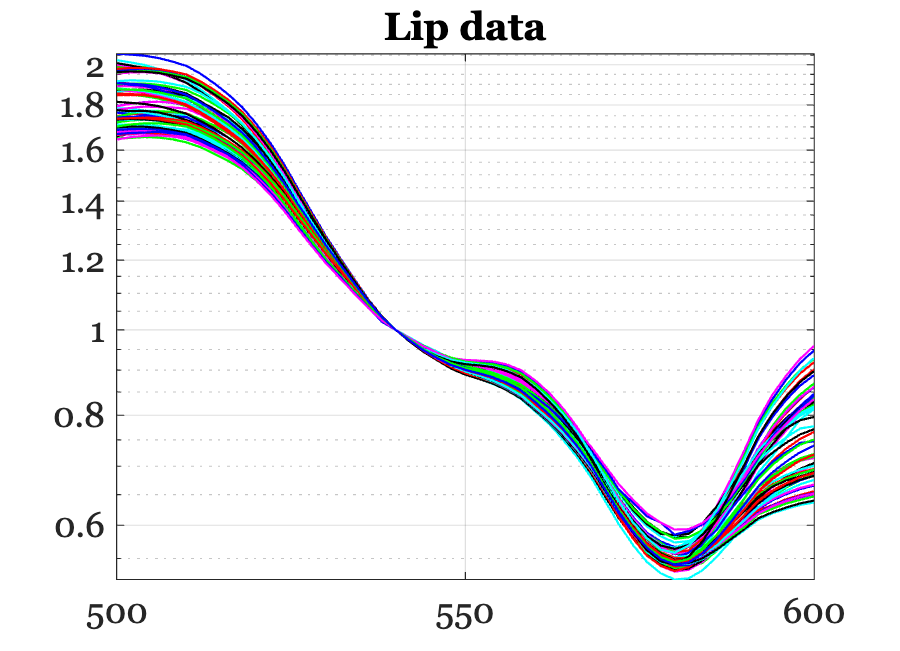

files405 = ieTableGet(T,...
    'ewave',405, ...
    'substrate','lip');
files415 = ieTableGet(T,...
    'ewave',415, ...
    'substrate','lip');
filesAll = cat(1,files405,files415);
dataLip = oeReadFiles(filesAll,'waves',waves,'normalized wave',normalizationP);

ieFigure;
semilogy(waves,dataLip);
grid on;
title('Lip data');

## Fit the lip data from the reduced tongue data

Without first calculating any bases, we can predict the lip data from the tongue data.  No basis approximation.

If they live in the same space, then it shouldn't be a problem.  They both have noise.  Not sure how that helps or hurts.

We find the matrix, M, such that we can multiply the tongue data and predict the lip data.


$${L_d =\;T}_d M$$


The special case would then be to replace the tongue data with a linear model approximation (say finding the basis functions) and use that subspace to make the prediction.  We do that below.

Here we try different dimensions of the tongue and see how well they fit the lip. We find that 4 dimensions of the Tongue data get the lip data too.

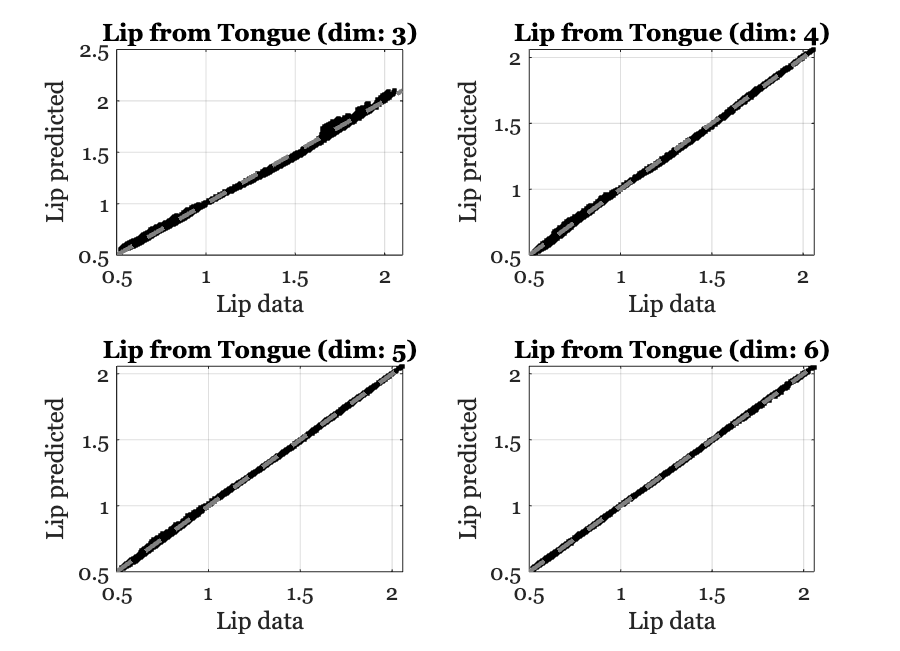

ieFigure;
tiledlayout(2,2)
for ii=3:6
    B = UT(:,1:ii);
    wgts = B'*dataTongue;
    dataTongueReduced = B*wgts;
    M = pinv(dataTongueReduced)*dataLip;
    dataLipP = dataTongueReduced*M;

    nexttile;
    plot(dataLip(:),dataLipP(:),'k.');
    xlabel('Lip data'); ylabel('Lip predicted'); grid on;
    title(sprintf('Lip from Tongue (dim: %d)',ii));
    identityLine;
end

## Find the lip bases

[UL, S, ~] = svd(dataLip, 'econ');


## Fit the lip data with several dimensions

The lip data are very well fit with three dimensions.

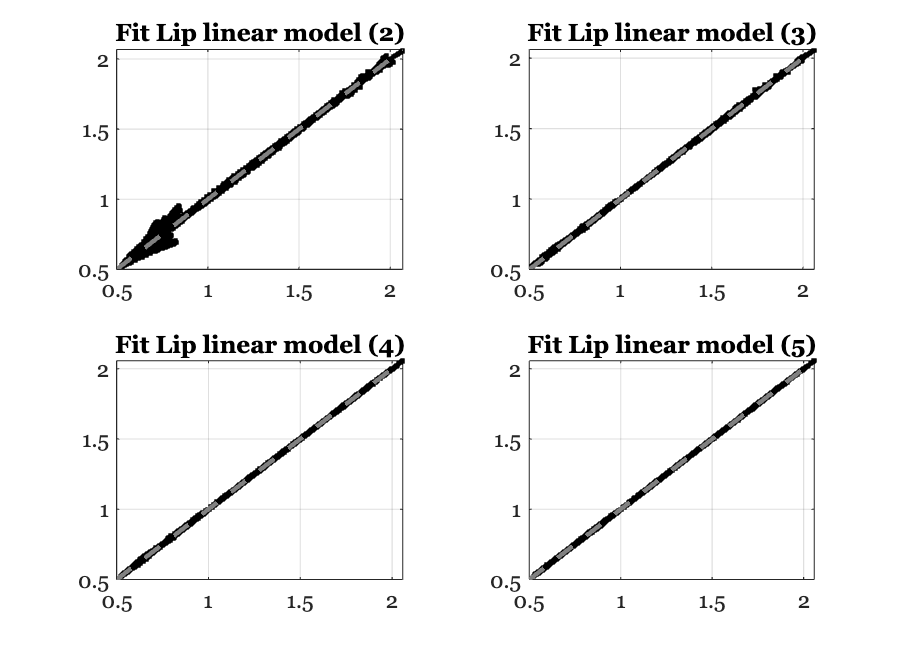

ieFigure;
tiledlayout(2,2)
for dd = dimensionality
    wgts = UL(:,1:dd)'*dataLip;
    est = UL(:,1:dd)*wgts;
    nexttile;
    plot(est(:),dataLip(:),'k.');
    identityLine;
    grid on;
    title(sprintf('Fit Lip linear model (%d)',dd));
end

## Fit the tongue with the lip bases

We need an extra dimension (4) to do reasonably using the lip bases to fit the tongue data.  We only do a little better with 5 or 6.

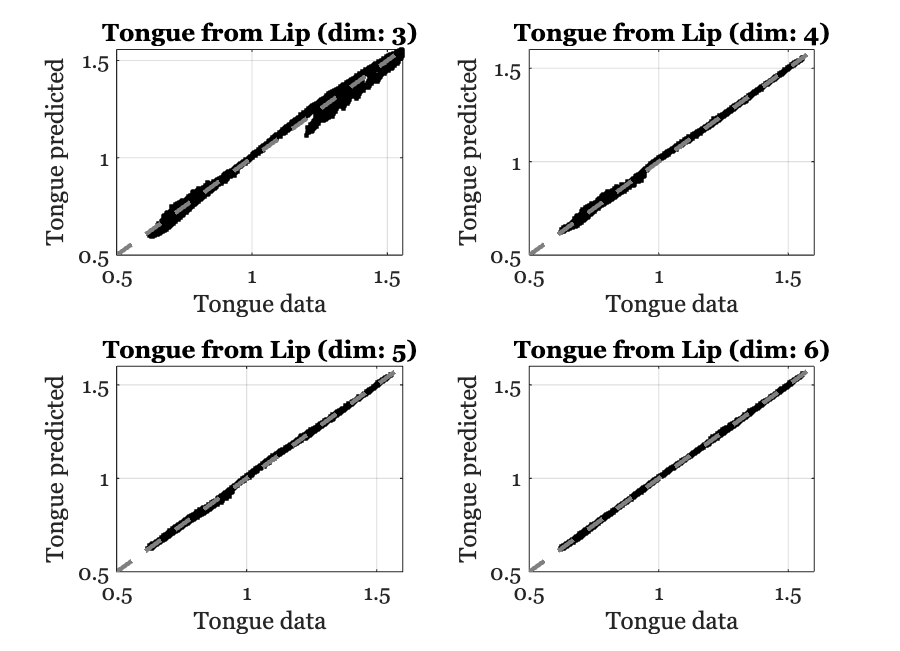

ieFigure;
tiledlayout(2,2)
for ii=3:6
    B = UL(:,1:ii);
    wgts = B'*dataLip;
    dataLipReduced = B*wgts;
    M = pinv(dataLipReduced)*dataTongue;
    dataTongueP = dataLipReduced*M;

    nexttile;
    plot(dataTongue(:),dataTongueP(:),'k.');
    xlabel('Tongue data'); ylabel('Tongue predicted'); grid on;
    title(sprintf('Tongue from Lip (dim: %d)',ii));
    identityLine;
end

## Is the problem tissue optics?

Suppose that there is a different wavelength filter in the tongue, $D_T$,  and lip, $D_L$.  Then we might have a pair of diagonal matrices that differ for the bases from the lip and tongue fluorophore signals.  We can combine the two diagonal matrices into one


$$D_{L\;} U_L =D_T U_T$$



$$U_L =D\;U_T$$


So a next project is to find a low-dimensional representation of the combined diagonal matrix, $D_\phi$, and search for its parameters, $\phi$ and the weights, $\omega$ that would satisfy


$$U_{L\;} =D_{\phi } U_T \omega$$


Here is a link to Gemini's solution in Matlab:  [https://g.co/gemini/share/1f70dfeefdde](https://g.co/gemini/share/1f70dfeefdde)

There is search code, written by ChatGPT, that we can check.  It takes oeSolveLipTongueCGPT() and returns the matrix and a diagonal.

% % Do the fit
% poly_degree = 6;
% [wgts, D_diag] = oeSolveLipTongueCGPT(UL, UT, poly_degree);
% disp(wgts)
% 
% % Show the Diagonal transmittance term.
% ieFigure; 
% plot(waves,D_diag,'k-');
% xlabel('Wavelength (nm)'); ylabel('Transmittance');

% % Compare the predicted and actual lip basis functions
% sym1 = {'r-','g-','b-','k-','m-','c-'};
% sym2 = {'r--','g--','b--','k--','m--','c--'};
% ULpred = diag(D_diag)*UT*wgts;
% 
% ieFigure;
% tiledlayout(rowcol,rowcol);
% % 
% for ii=1:size(UL,2)
%     nexttile;    
%     hA = plot(waves,ULpred(:,ii),sym1{ii}); hold on;
%     hB = plot(waves,UL(:,ii),sym2{ii}); hold on;
% end
% 
% legend([hA,hB],{'Predicted UL from UT','UL'});
% % xaxisLine;
% grid on;

## Now predict the data

% UTDiag = diag(D_diag)*UT;
% wgts = pinv(UTDiag)*dataLip;
% dataLipP = UTDiag*wgts;
% 
% ieFigure;
% plot(dataLip(:),dataLipP(:),'k.');
% grid on; xlabel('Lip Data'); ylabel('Lip Predicted');
% identityLine;